folder = "D:\Whale Data\Raw Audio Data\CaseyIslands2017";
dsname = "CaseyIslands2017";

detectors = load(folder + "\\detectors\\detectors.mat").D;
fileidx = 9:748; %first 28 files are clipping and corrupt
segmm = [detectors.segmms1white];
segmm = segmm(fileidx);
anns = {detectors.annotations};
info = [detectors.info];

conv = arrayfun(@(d) d.converged, segmm);
segmmconv = segmm(conv);
annsconv = anns(conv);
infoconv = info(conv);

load(folder + "\\scattering\\filterbank.mat");
fsscat = fb.filterBanks(1).getSSamplingFreq()

fsscat = 6.2500

%use the detector's output annotate and distinguish from noise
r = 0.6;
rles = arrayfun(@(d) getDetRLE(d, r), segmmconv, UniformOutput=false);

idx = 1:numel(rles);
tidx = ThreadIdx(numel(rles), 6);
rlews = {};
for spmdIndex = 1
    while ~tidx.complete(spmdIndex)
        i = tidx.next(spmdIndex);
        rlews{end+1} = getDetScatCoeff(annsconv{i}, rles{i}, infoconv(i), folder, i, fb.pathstart, fsscat);
    end
end

dl = DataLoader2(folder + "\scattering", 'mat', 'parallel', true);
annotations = load(folder + "\anotations\annotations.mat").annotationTable;
fb = load(folder + "\scattering\filterbank.mat").fb;
Ns1 = numel(fb.filterBanks(1).lambdas);


spmd
    while ~dl.isComplete(spmdIndex)
        [s, info, fs] = dl.next(spmdIndex);
        ann = annotations(annotations.File == replace(info.name, ".mat", ".wav"), :);
        s = s.^2;
        s1 = s(1:Ns1, :);
        sw = noiseEstimate(s1, 9, floor(120/2*fs)*2 + 1);
        s1w = s1./sw;
        segmm = SEGMM(floor(1.5*fs/2)*2 + 1);
        segmm.detect(s1w);
        if ~segmm.converged
            continue;
        end
        rle = Tools.rle(Tools.threshhyst(segmm.probs, 0.5, 0.25));
        extend_n = floor(fs*0);
        data = cell2table(cell(0, 4), 'VariableNames',["File", "Annotation", "Scattering", "AnnotationPower"])
        for i = 1:size(rle, 1)
            r = rle(i, :);
            ovr = r.Start <= ann.ScatteringEndIndex & ann.ScatteringStartIndex <= r.End;
            ss = max(rle.Start - extend_n, 1);
            se = min(rle.End + extend_n, size(s, 2));
            coeffs = mean(s(:, ss:se),  2);
            coeffs = cosineLogScattering(coeffs, pathstart);
            V = {[coeffs, rle.End-rle.Start]};
            annotation = "Noise";
            annsum = 0;
            if sum(ovr) == 1
                annotation = ann.Annotation(ovr);
                fc = fb.filterBanks(1).fc;
                fidx = fc >= ann.StartFrequency & fc <= ann.EndFrequency;
                annsum = sum(s1w(fidx,ann.ScatteringStartIndex:ann.ScatteringEndIndex), "all");
            elseif sum(ovr) > 1
                annotation = "Multiple";
            end
        end

    end
    
end

temp = rlews(:);
temp = [rlews{:}];
rlewsall = vertcat(temp{cellfun(@(t) size(t, 1) > 0, temp)});
% clear temp

counts = groupcounts(rlewsall, "Annotation")

counts = 9×3 table
         Annotation         GroupCount     Percent 
    ____________________    __________    _________

    "Bm_Ant-A"                  709          2.6976
    "Bm_Ant-B"                  188         0.71529
    "Bm_Ant-Z"                   44         0.16741
    "Bm_D"                      117         0.44515
    "Bp_20Hz"                     1       0.0038047
    "Bp_20Plus"                  18        0.068485
    "Multiple"                   37         0.14078
    "Noise"                   25131          95.617
    "Unidentified_calls"         38         0.14458


save(folder + "\\features\\features.mat", "rlewsall", '-mat');


rlewsall = rlewsall(rlewsall.Annotation ~= "Multiple" & rlewsall.Annotation ~= "Uncertain", :); %do not consider overlapping annotations

y = rlewsall{:, "Annotation"};
y = replace(y, "-", "_");
% y(contains(y, "Bm_Ant")) = "Bm_Ant";
annotations = unique(y);
classes = annotations;
% y(contains(y, "Bm")) = "Blue";
y(contains(y, "Bp")) = "Noise";
% y(contains(y, "Bm")) = "Signal";
% other = ~(y == "Blue" | y == "Fin");
% other = ~(y == "Signal");
% other = ~any(y == classes', 2);
other = ~contains(y, "Bm");
y(other) = "Noise";
classes = unique(y)

classes = 5×1 string array
    "Bm_Ant_A"
    "Bm_Ant_B"
    "Bm_Ant_Z"
    "Bm_D"
    "Noise"


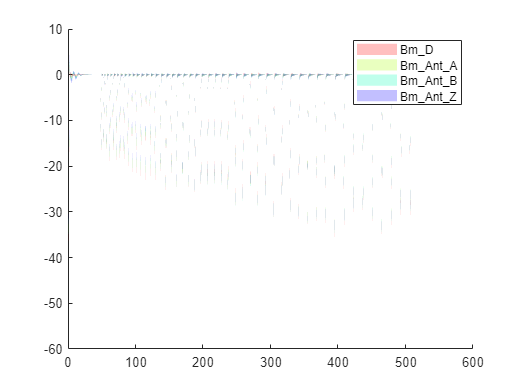


X = rlewsall{:, "WS"};
X = vertcat(X{:});


colors = ones(numel(classes), 3);
colors(:, 1) = linspace(0, 0.9, numel(classes));
colors = hsv2rgb(colors);
B = arrayfun(@(f) size(f.Psi, 1), fb.filterBanks);
for i = 1:numel(B)
    klen(i) = prod(B(1:i));    
end
kend = cumsum(klen);
kstart = [1, kend(1:end-1)];
figure
hold on
classes = ["Bm_D", "Bm_Ant_A", "Bm_Ant_B", "Bm_Ant_Z"];

for i = 1:numel(classes)
    c = classes(i);
    col = colors(i, :);    
    mu = mean(X(y == c, 1:end-1), 1);
    sigma = mad(X(y == c, 1:end-1), 1);
    f = 1:size(X, 2) - 1;
    fill([f, fliplr(f)], [mu + sigma, fliplr(mu-sigma)], col, "FaceAlpha", 0.25, "LineStyle","none")    
end

minx = -1.5;
maxx = 5.5;
% for i = 1:2
%     fill([kstart(i), kstart(i), kend(i), kend(i)], [minx, maxx, maxx, minx], "black", ...
%         "FaceColor","none", LineStyle=":")
%     text(kstart(i) + (kend(i) - kstart(i))/2, maxx, sprintf("$\\mathcal{S}_%d x$", i), ...
%         "HorizontalAlignment","center", "VerticalAlignment","bottom", "FontSize",12, "Interpreter","latex")
% end
hold off
legend(classes, "Interpreter","none")

% ylim([-2, 6])
% xticks([kstart, kend(end)])
% xlim([-10, kend(end) + 10])


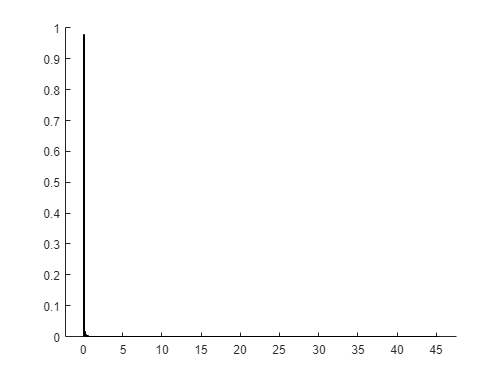


Xr = aenc.predict(Xtest);
xmse = mean((Xr - Xtest).^2, 1);
figure
hold on
histogram(xmse, 500, "Normalization","probability");

Xr = aenc.predict(Xsig);
xmse = mean((Xr - Xsig).^2, 1);
histogram(xmse, 20, "Normalization","probability");
hold off

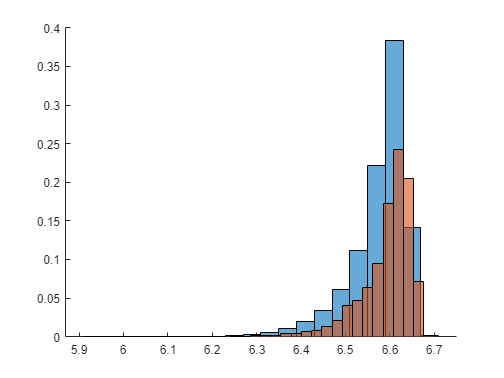

X = rlewsall{:, "WS"};
X = double(vertcat(X{:}));
y = rlewsall{:, "Annotation"};
Xn = X./median(X(y == "Noise", :), 1);
Xnoise = Xn(y == "Noise", :);
Xsig = Xn(y ~= "Noise", :);

XnoiseH = entropyWS(Xnoise);
XsigH = entropyWS(Xsig);
figure
hold on
histogram(XnoiseH, 20, "Normalization","probability")
histogram(XsigH, 20, "Normalization","probability")
hold off

function T = getDetRLE(det, r)
    if r > 1
        labels = det.probs > r*min(det.probs);
    else
        sc = det.Hmax - det.Hmin > snr2dh(db2mag(-100), 48);
        labels = det.probs * sc > r;
    end
    T = Tools.rle(labels);
    T.Prob = arrayfun(@(i) max(det.probs(T.Start(i):T.End(i))), 1:size(T, 1))';
end

function detrle = getDetScatCoeff(ann, detrle, info, path, idx, pathstart, fsfb)
%     d = fsspec/fsscat;
    if mod(idx, 100) == 0
        idx
    end
    fname = info.name;
    s = double(load(path + "\\scattering\\" + fname).s);
%     ann = ann(ann.AnnotationToNoiseRatioDB > anrdb, :);
%     mu = median(s, 2);
%     p = mean(median(s, 2), "all");
%     s = max(s - mu, 1e-12);
%     s = s./mu;
%     madfb1 = median(s(1:endfb1, :), 2);
%     s(1:endfb1, :) = s(1:endfb1, :)./madfb1 - 1;
%     s = max(s - median(s, 2), 1e-12);
    extend_n = ceil(0*fsfb);
    for i = 1:size(detrle, 1)
        rle = detrle(i, :);
        ovr = rle.Start <= ann.ScatteringEndIndex & ann.ScatteringStartIndex <= rle.End;
        ss = max(rle.Start - extend_n, 1);
        se = min(rle.End + extend_n, size(s, 2));
        coeffs = mean(s(:, ss:se),  2);
        coeffs = cosineLogScattering(coeffs, pathstart);
        detrle.WS(i) = {[coeffs, rle.End-rle.Start]};
        if sum(ovr) == 1
            detrle.Annotation(i) = ann.Annotation(ovr);            
        elseif sum(ovr) > 1
            detrle.Annotation(i) = "Multiple";
        else
            detrle.Annotation(i) = "Noise";
        end
    end

end

function cls = cosineLogScattering(coeffs, pathstart)
    coeffs = log(coeffs);
    pathstart = [pathstart, numel(coeffs)+1];
    cls = zeros(1, numel(coeffs));
    for i = 1:numel(pathstart)-1
        s = pathstart(i);
        e = pathstart(i+1) - 1;
        cls(s:e) = dct(coeffs(s:e))'; %compute along each path
    end
%     %ignore the DC offset which results from noise
%     idx = setdiff(1:numel(coeffs), pathstart(1:end-1)); 
%     cls = cls(idx);
end


function H = entropyWS(X)
    s = sum(X, 2);
    Xn = X./s;
    H = -sum(Xn.*log(Xn), 2);
end